# CÓDIGO DESENVOLVIDO BASEADO NA SOLUÇÃO DE NAVIER UTILIZANDO A FORMULAÇÃO GUF

# CLEANING

clc; clear; close all

## APPROXIMATION

APP = [2 2 2]; 

## MATERIAL - ISOTROPIC

% MATERIAL 1
mat(1).E = 1; % YOUNG MODULUS
mat(1).nu = 0.25;  % POISSON RATIO  

## GEOMETRY

% LAYER 1
geo(1).h = 1;         % THICKNESS
geo(1).z_top = geo(1).h/2;
geo(1).z_low =-geo(1).h/2;
geo(1).theta = 0;  % ANGLE
geo(1).a = 1;
geo(1).b = 3;
geo(1).m = 1;
geo(1).n = 1;

## APPLIED PRESSURE

%    X Y Z
P = [0 0 100;  % TOP
     0 0 0]; % BOTTOM
NL = length(geo);

## THEORY

theory = 'EQ'; % LW - LAYERWISE
               % EQ - EQUIVALENT SINGLE LAYER

## STIFFNESS MATRIX

[ kernel ] = pre_locating_K( theory, NL, APP );
for i = 1 : NL
    [ stiffness ] = classic_Hook_iso( mat, geo, i );
    [ kernel ] = kernel_PVD( stiffness, geo, i, kernel, theory);
end

## PRESSURE

[ pressure ] = pressure_PVD( APP, P );
[ D ] = D_matrix_PVD( APP, geo );

## REACTION FORCES

Reaction.x = D.uxux_t*pressure.top.x + D.uxux_b*pressure.bot.x;
Reaction.y = D.uyuy_t*pressure.top.y + D.uyuy_b*pressure.bot.y;
Reaction.z = D.uzuz_t*pressure.top.z + D.uzuz_b*pressure.bot.z;

reaction = [ Reaction.x; Reaction.y; Reaction.z ];

## ASSEMBLY

Kernel = assembly_PVD( kernel );

## DISPLACEMENT

U = Kernel\reaction;

## STRESS

[ sigma ] = stress(APP, geo, stiffness, U, 0.25);

fprintf('sigma xx = %4.6f \n',sigma.xx/P(1,3))

sigma xx = 0.235651 


fprintf('sigma yy = %4.6f \n',sigma.yy/P(1,3))

sigma yy = 0.228388 


fprintf('sigma xy = %4.6f \n',sigma.xy/P(1,3))

sigma xy = -0.002723 


fprintf('sigma zx = %4.6f \n',sigma.xz/P(1,3))

sigma zx = 0.325690 


fprintf('sigma zy = %4.6f \n',sigma.yz/P(1,3))

sigma zy = 0.108563 


fprintf('sigma zz = %4.6f \n',sigma.zz/P(1,3))

sigma zz = 0.673364 


## POST-PROCESSING

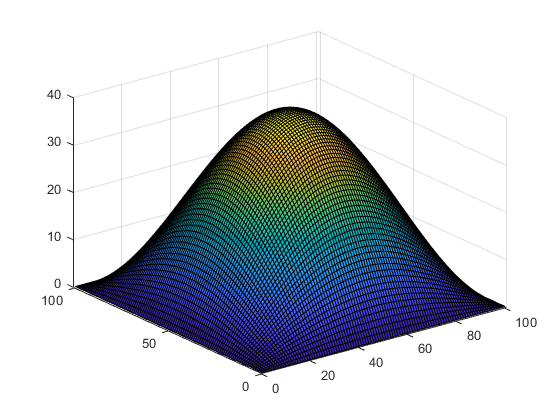

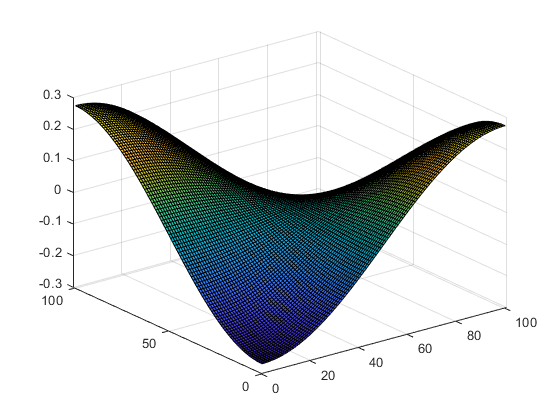

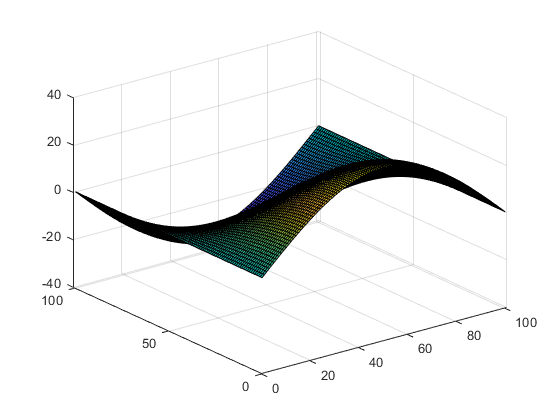

Navier_post_processing(APP, geo, sigma, U, 0.25);